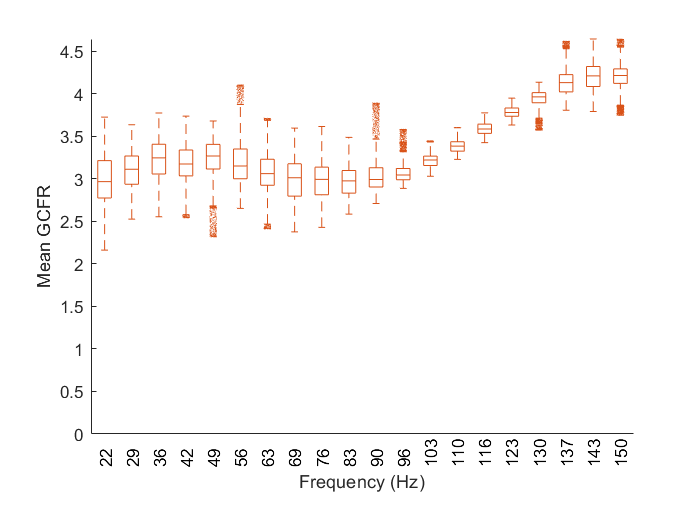

P_idx=2;
avg_gcfr = P(P_idx).avg_gcfr(start_stim:stop_stim-1);
freq_continuous = P(P_idx).inc_frq_chirp_f(1:end-1);

avg_gcfr_reshape = reshape(avg_gcfr,[],20);
freq_discrete = linspace(freq_continuous(1), max_chirp_frq, 20);

% f = tiledlayout(1,1);
% ax1 = axes(f);
% plot(ax1,freq_continuous,avg_gcfr,'-k')
% ax1.XColor = 'k';
% ax1.YColor = 'k';

% ax2 = axes(f);
figure;
boxplot(avg_gcfr_reshape,round(freq_discrete),'PlotStyle','compact', 'BoxStyle',"outline","Colors",[0.8500 0.3250 0.0980],'MedianStyle',"line", "Symbol",'o',"OutlierSize",0.2);

xlabel('Frequency (Hz)');
ylabel('Mean GCFR');
ylim([0 inf]);
box  off;

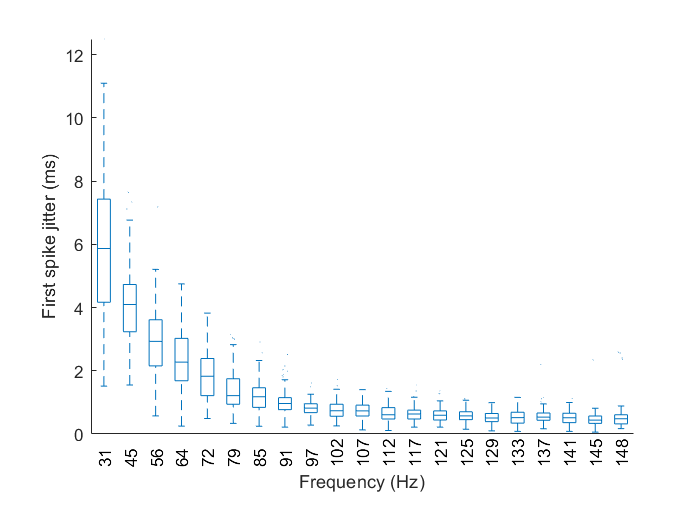


% ax2.XAxisLocation = 'top';
% ax2.YAxisLocation = 'right';
% ax2.Color = 'b';
% ax1.Box = 'off';
% ax2.Box = 'off';


freq_discrete_jitter = mean(reshape(I_spike,[],21),1);
I_spike_jitter = reshape(spike_time_sd,[],21);

figure;
boxplot(I_spike_jitter*1000,round(freq_discrete_jitter),'PlotStyle','compact', 'BoxStyle',"outline","Colors",[0 0.4470 0.7410],'MedianStyle',"line", "Symbol",'o',"OutlierSize",0.2);
xlabel('Frequency (Hz)');
ylabel('First spike jitter (ms)');
ylim([0 inf]);
box  off;